# combine mask dataset generate


%% orig scene
% load('init_test.mat', 'orig');
load('init_test_8f.mat', 'orig');


%% init mask
% load
% init_mask = load('init_test.mat', 'mask');
init_mask = load('init_test_8f.mat', 'mask');
init_mask = init_mask.mask;
img_num = size(init_mask,3);
img_size = [size(init_mask,1) size(init_mask,2)];

% random generate
% img_size = [512 512]; img_num=4;
% img_size = [256 256]; img_num=8;
% init_mask = gray_mask([img_size,img_num]); % uniform
% init_mask = gray_mask([img_size,img_num]); % gaussian


%% combine matrix
% combine_matrix = eye(img_num); % non-combine
% 4 frame
% combine_matrix = [1 1 0 0; 0 1 1 0; 0 0 1 1; 0 1 0 1]; % combine1
% combine_matrix =  [1 1 0 0; 0 1 1 0; 0 0 1 1; 1 1 0 1];% combine2
% combine_matrix = [1 0 1 0; 0 1 1 1; 0 0 1 1; 1 1 0 1]; % combine3
% combine_matrix = [1 0 1 1; 0 1 1 1; 0 0 1 1; 1 1 0 1]; % combine4
% combine_matrix = [0 1 1 1; 1 0 1 1; 1 1 0 1; 1 1 1 0]; % combine5
% combine_matrix = [1 1 0 0; 0 1 1 0; 0 0 1 1; 1 0 0 1]; % combine6 - Not full rank, rank=3
% combine_matrix = [1 1 1 0; 0 1 1 1; 1 0 1 1; 0 1 1 1]; % combine7 - Not full rank, rank=3, mask2=mask4
% combine_matrix = [1 1 0 0; 0 1 1 0; 0 0 1 1; 0 1 1 0]; % combine8 - Not full rank, rank=3, rank=3, mask2=mask4

% 8 frame
% random generation combine_matrix
% combine_matrix = single(binary_mask(img_num)); % combine1

% load combine_matrix
% load('combine_matrix_8f_1.mat', 'combine_matrix');
% load('combine_matrix_8f_2.mat', 'combine_matrix');
% load('combine_matrix_8f_3.mat', 'combine_matrix');

% specified combine matrix




rank_combine_matrix = rank(combine_matrix)
mask = combine_mask(init_mask,combine_matrix);

mask = single(mask);
% histgram
figure,hist(init_mask(:),10)
figure,hist(mask(:),10)
mean_mask1 = mean(mask,'a')
% [r,p,ar,ap] = matrix_corr(mask)



%% coding frame
coded_frame = single(mask).*single(orig);
meas = sum(coded_frame, 3);
% coded_frame = single(mask).*single(orig);
% meas = sum(coded_frame, 3);
mean_meas1 = mean(meas,'a')


%% normalize
% [mask, meas] = dvpdata_normalize(mask, meas);
% mask_max = max(mask,[],'a')
% mask = mask./ mask_max;
% meas = meas./ mask_max;
mean_mask2 = mean(mask,'a')
mean_meas2 = mean(meas,'a')


%% save dataset
save('test.mat','combine_matrix','init_mask','orig','mask','meas', '-v7.3')
% save('test_8f.mat','combine_matrix','init_mask','orig','mask','meas', '-v7.3')
% save('test.mat','orig','mask','meas','-v7.3')
% save('test.mat','orig','mask','meas','-v7.3')

# specialize random mask dataset generate

% flags
dvp_flag=1;

% params
img_num = 10;
% img_size = [512 512];
img_size = [256 256];

%% load orig
% orig = load('init_test.mat', 'orig')
% orig = load('traffic.mat', 'orig')

load_dataset_folder = 'E:\project\CACTI\SCI algorithm\[dataset]\#benchmark\orig\bm_256_10f\';
% load_dataset_name = 'aerial.mat';
% load_dataset_name = 'crash.mat';
% load_dataset_name = 'drop.mat';
% load_dataset_name = 'kobe.mat';
% load_dataset_name = 'runner.mat';
load_dataset_name = 'traffic.mat';
orig = load([load_dataset_folder load_dataset_name], 'orig')

orig = 包含以下字段的 struct :
    orig: [256×256×10 double]


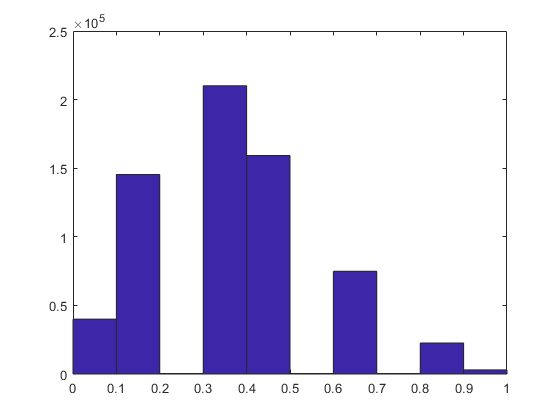


orig = orig.orig;
orig = orig(:,:,1:img_num);
if size(orig,1) ~= img_size(1)
    orig =imresize(orig, img_size);
end
% orig = orig/255;

%% mask
% load
% init_mask = load('init_test.mat', 'mask');
% init_mask = load('512scale_traffic_cacti_simu.mat', 'mask');
init_mask = load("E:\project\CACTI\SCI algorithm\[dataset]\#benchmark\mask\combine_binary_mask_256_10f.mat", 'mask');
init_mask = init_mask.mask;
mask = init_mask(:,:,1:img_num);
mask = single(mask);

% generate
% mask = gray_mask([img_size,img_num]);
% mask = single(binary_mask([img_size,img_num]));

figure,hist(mask(:),10)

mean_mask1 = mean(mask,'a')

mean_mask1 = single
0.3749



%% coding frame
coded_frame = single(mask).*single(orig);
meas = sum(coded_frame, 3);


%% normalize
mask_max = max(mask,[],'a')
mask = mask./ mask_max;
meas = meas./ mask_max;

figure,hist(mask(:),10)

mean_mask2 = mean(mask,'a')

mean_mask2 = single
0.3749

mean_meas2 = mean(meas,'a')

mean_meas2 = single
401.1370


if dvp_flag
    % save dataset for dvp
    dataset_dir = './'
%     dataset_dir = 'E:\project\CACTI\simulation\CI algorithm\PnP-SCI\dataset\simdata\zzh_data\'
%     dataset_dir = 'E:\project\CACTI\simulation\CI algorithm\dvp\dvp_inv\dataset\'
%     dataset_name = 'test.mat';
    dataset_name = load_dataset_name;
    save([dataset_dir 'data_' dataset_name],'orig','mask','meas','-v7.3')
end

dataset_dir = './'

# data feature parameter evaluation

% data feature parameter evaluation
% orig
min_orig = min(orig,[],'all')
mean_orig = mean(orig,'a')
max_orig = max(orig,[],'all')

% init_mask
% min_init_mask = min(init_mask,[],'all')
% mean_init_mask = mean(init_mask,'a')
% max_init_mask = max(init_mask,[],'all')
% [r,p,ar,ap] = matrix_corr(init_mask)
% figure,hist(mask(:),10)

% mask
min_mask = min(mask,[],'all')
mean_mask = mean(mask,'a')
max_mask = max(mask,[],'all')
figure,hist(mask(:),10)
% [r,p,ar,ap] = matrix_corr(mask)

% meas
min_meas = min(meas,[],'all')
mean_meas = mean(meas,'a')
max_meas = max(meas,[],'all')
% [r,p,ar,ap] = matrix_corr(mask)

# dataset sampling

% dataset sampling
init_dataset_dir = 'E:\project\CACTI\SCI algorithm\[dataset]\#benchmark\orig\bm_256\';
dst_dataset_dir = 'E:\project\CACTI\SCI algorithm\[dataset]\#benchmark\orig\bm_256_10f\';

files = dir([init_dataset_dir '*.mat']);
file_names = {files.name};

for file_name = file_names
    file_name_str = char(file_name);
    load([init_dataset_dir file_name_str]);
    orig = orig(:,:,1:10);
    
    [~, data_name, ext] = fileparts(file_name_str);
    save([dst_dataset_dir data_name ext] ,'orig')
end

